# Toy problems in SE(2)

## Group Actions

Let's start by initializing two arbitrary SE(2) group elements `g `and `h`.

We shall be visualizing their vector and matrix forms (group actions happen when they are in their matrix form).

% Initialize the variables to work with:
syms x y theta u v beta real

% V2M M2V functions:
v2M_SE2 = @(v) [cos(v(3)), -sin(v(3)), v(1);
                sin(v(3)),  cos(v(3)), v(2);
                        0,         0,    1];

M2v_SE2 = @(M) simplify([M(1,3); 
                M(2,3);
                atan(M(2,1)/M(1,1))], 'Steps', 10, ...
                'IgnoreAnalyticConstraints', true);

% Group action functions:
L_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(h)*v2M_SE2(g)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 
R_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(g)*v2M_SE2(h)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 

% Group lifted-actiion functions:
T_gL_h = @(g,h) jacobian(L_h_ofg(g,h), g); T_gR_h = @(g,h) jacobian(R_h_ofg(g,h), g);

% Define the vector form of two points in our group 'g', 'h', and 'e':
g_vec = [x;
         y;
         theta]

$$g\_vec = \left(\begin{array}{c} x\\ y\\ \theta \end{array}\right)$$

h_vec = [u;
         v;
         beta]

$$h\_vec = \left(\begin{array}{c} u\\ v\\ \beta \end{array}\right)$$

e_vec = [0;
         0;
         0] % 'e' is the identity and in a more traditional sense the origin for the manifold

e_vec =      0
     0
     0


% Get the matrix forms for these vectors:
g_mat = v2M_SE2(g_vec)

$$g\_mat = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & x\\ \sin\left(\theta \right) & \cos\left(\theta \right) & y\\ 0 & 0 & 1 \end{array}\right)$$

h_mat = v2M_SE2(h_vec)

$$h\_mat = \left(\begin{array}{ccc} \cos\left(\beta \right) & -\sin\left(\beta \right) & u\\ \sin\left(\beta \right) & \cos\left(\beta \right) & v\\ 0 & 0 & 1 \end{array}\right)$$

e_mat = v2M_SE2(e_vec)

e_mat =      1     0     0
     0     1     0
     0     0     1


Let's show how a group action works step-by-step,

eg = simplify(h_mat*g_mat, 'Steps', 10)

$$eg = \left(\begin{array}{ccc} \cos\left(\beta +\theta \right) & -\sin\left(\beta +\theta \right) & u+x\,\cos\left(\beta \right)-y\,\sin\left(\beta \right)\\ \sin\left(\beta +\theta \right) & \cos\left(\beta +\theta \right) & v+y\,\cos\left(\beta \right)+x\,\sin\left(\beta \right)\\ 0 & 0 & 1 \end{array}\right)$$

Now, if we write it in the vector form, we get,

eg = simplify([eg(1,3); 
          eg(2,3);
          atan(eg(2,1)/eg(1,1))], 'Steps', 10, 'IgnoreAnalyticConstraints', true)

$$eg = \left(\begin{array}{c} u+x\,\cos\left(\beta \right)-y\,\sin\left(\beta \right)\\ v+y\,\cos\left(\beta \right)+x\,\sin\left(\beta \right)\\ \beta +\theta \end{array}\right)$$

The angles have obviously added up, and the vector $\left\lbrack x,y\right\rbrack$ is rotated by $\beta$. 

We shall use the previously functions to do the rest of the computation,

% Let's perform some group actions as a sanity check ~ matrix first, then
% vector form
hg_vec = L_h_ofg(g_vec, h_vec)

$$hg\_vec = \left(\begin{array}{c} u+x\,\cos\left(\beta \right)-y\,\sin\left(\beta \right)\\ v+y\,\cos\left(\beta \right)+x\,\sin\left(\beta \right)\\ \beta +\theta \end{array}\right)$$

gh_vec = R_h_ofg(g_vec, h_vec)

$$gh\_vec = \left(\begin{array}{c} x+u\,\cos\left(\theta \right)-v\,\sin\left(\theta \right)\\ y+v\,\cos\left(\theta \right)+u\,\sin\left(\theta \right)\\ \beta +\theta \end{array}\right)$$

## Group Lifted Actions - Mapping tangent spaces

Next, we shall implement the left and right lifted actions that map velocities in 'g' to velocities in 'gh' or 'hg',

% Now, we can try lifted actions:
T_g_to_T_hg = T_gL_h(g_vec, h_vec)

$$T\_g\_to\_T\_hg = \left(\begin{array}{ccc} \cos\left(\beta \right) & -\sin\left(\beta \right) & 0\\ \sin\left(\beta \right) & \cos\left(\beta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

T_g_to_T_gh = T_gR_h(g_vec, h_vec)

$$T\_g\_to\_T\_gh = \left(\begin{array}{ccc} 1 & 0 & -v\,\cos\left(\theta \right)-u\,\sin\left(\theta \right)\\ 0 & 1 & u\,\cos\left(\theta \right)-v\,\sin\left(\theta \right)\\ 0 & 0 & 1 \end{array}\right)$$

These results match the equations described in section A.3 of  this paper [https://link.springer.com/article/10.1140/epjst/e2015-50085-y](https://link.springer.com/article/10.1140/epjst/e2015-50085-y) 

With this understanding, we can try to replicate results in section 3.1.2 in the same paper. Some important lifted actions that will help us define local (body frame) velocity, global (rest frame) velocity, and spatial velocity (think what velocity should the global frame have to produce the same body velocity relatively) are needed to conclude this review before moving onto an example.

% Compute the inverse of a group element -- we do this by first converting
% it to the matrix form, then take its inverse, and finally pull it back to
% the vector form.
gInv_mat = simplify(inv(g_mat), 'Steps', 10)

$$gInv\_mat = \left(\begin{array}{ccc} \cos\left(\theta \right) & \sin\left(\theta \right) & -x\,\cos\left(\theta \right)-y\,\sin\left(\theta \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right) & x\,\sin\left(\theta \right)-y\,\cos\left(\theta \right)\\ 0 & 0 & 1 \end{array}\right)$$

gInv_vec = M2v_SE2(gInv_mat)

$$gInv\_vec = \left(\begin{array}{c} -x\,\cos\left(\theta \right)-y\,\sin\left(\theta \right)\\ x\,\sin\left(\theta \right)-y\,\cos\left(\theta \right)\\ -\theta \end{array}\right)$$

In order to obtain the ***body velocity*** from the global velocity, we need to map from the tangent space at global frame to the tangent space at the body frame of the robot (tangent space is the space where the velocities of group elements are defined -- $\forall g \in G$, $\dot{g} \in T_e G$),


$$\overset{\circ}{\text{g}} = \frac{\partial{e}}{\partial{g}} \dot{g} = \frac{\partial{g^{-1} g}}{\partial{g}} \dot{g} = T_g L_{g^{-1}} \: \dot{g}$$


Since, we already have $g^{-1}$, we can get the corresponding left-lifted action,

TgLgInv = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta],...
    [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)]))

$$TgLgInv = \left(\begin{array}{ccc} \cos\left(\theta \right) & \sin\left(\theta \right) & 0\\ -\sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Similar to this, we can get the ***spatial velocity***,


$$\overset{\circ}{\text{g}^S} = \frac{\partial{e}}{\partial{g}} \dot{g} = \frac{\partial{g g^{-1}}}{\partial{g}} \dot{g} = T_g R_{g^{-1}} \: \dot{g}$$


TgRgInv = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)]))

$$TgRgInv = \left(\begin{array}{ccc} 1 & 0 & y\\ 0 & 1 & -x\\ 0 & 0 & 1 \end{array}\right)$$

Wwe compute the global velocity from body velocity as follows,


$$\dot{g} = \frac{\partial{g}}{\partial{e}} \: \overset{\circ}{\text{g}} = \frac{\partial{ge}}{\partial{e}} \: \overset{\circ}{\text{g}} = T_e L_g \: \overset{\circ}{\text{g}}$$


TeLg = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta]))

$$TeLg = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

And finally, we compute the global velocity from spatial velocity,


$$\dot{g} = \frac{\partial{g}}{\partial{e}} \: \overset{\circ}{\text{g}^S} = \frac{\partial{eg}}{\partial{e}} \: \overset{\circ}{\text{g}^S} = T_e R_g \: \overset{\circ}{\text{g}^S}$$


TeRg = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta]))

$$TeRg = \left(\begin{array}{ccc} 1 & 0 & -y\\ 0 & 1 & x\\ 0 & 0 & 1 \end{array}\right)$$

As expected, it just rotates the body frame velocity by $\theta \;\ldotp$

## Adjoint inverse maps in the tangent space

The adjoint-inverse mapping encodes the transfer of velocity between frames on a rigid body. It can be split up into two successive transformations,

- cross product

- inverse rotation

The adjoint-inverse of map between tangent spaces $T_{h_1} G$ and $T_{h_i} G$ is $ \overset{\circ}{\text{h}_i} = Ad^{-1}_{g}  \overset{\circ}{\text{h}_1}$, where g is the transformation between the group elements. Using our initial definition of $g = (x, y, \theta)$, the adjoint inverse map $Ad^{-1}_{g}$ is given by,


$$\left\lbrack \begin{array}{ccc}
\cos \;\theta  & \sin \;\theta  & 0\\
-\sin \;\theta  & \cos \;\theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & -y\\
0 & 1 & x\\
0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\cos \;\theta  & \sin \;\theta  & x\;\sin \;\theta \;-y\;\cos \;\theta \;\\
-\sin \;\theta  & \cos \;\theta  & x\;\cos \;\theta \;+y\;\sin \;\theta \\
0 & 0 & 0
\end{array}\right\rbrack$$


Let's now define this as an inline function to use later,

AdjInvMap = @(k) simplify(...
    subs(TgLgInv, theta, k(3))*subs(TeRg, [x y], [k(1) k(2)])...
    , 'Steps', 10);

## 2-legged system with pins at the foot

Consider an SE(2) system with 2 legs at diametrically opposite ends of a disk centered at the body center, and the right foot is highlighted in the figure below because it is pinned to the ground.

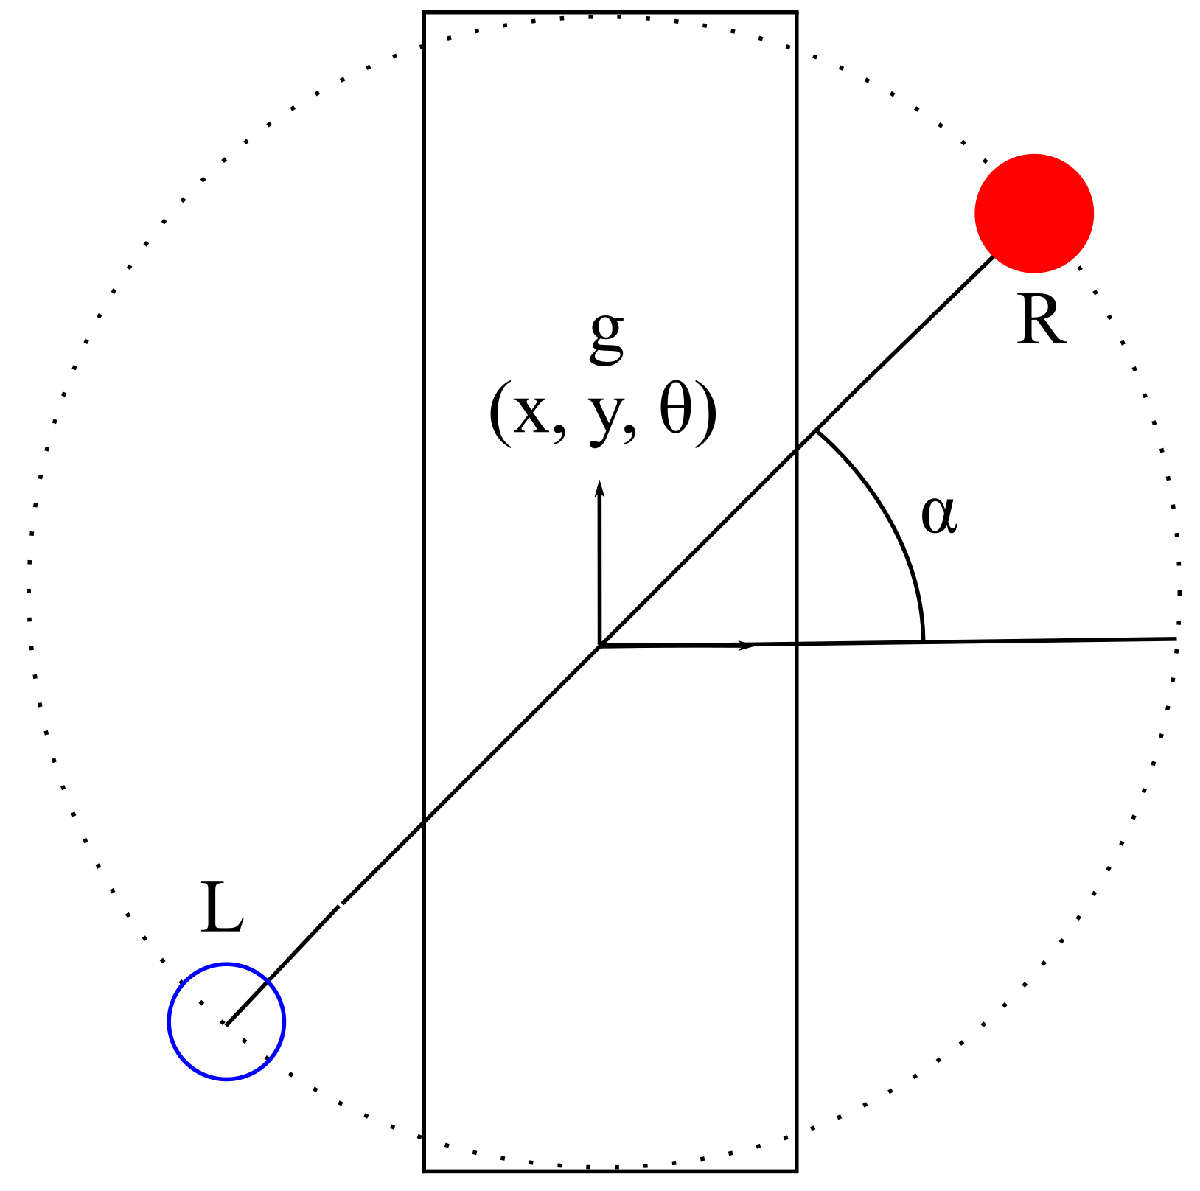

### Transforms and Jacobians

The transforms (denoted by 'h' and the frame name in the subscript) to the feet are pretty straightforward,

syms r alpha alpha_dot real
% Transform to the right leg:
h_R = [r*cos(alpha);
       r*sin(alpha);
       alpha]

$$h\_R = \left(\begin{array}{c} r\,\cos\left(\alpha \right)\\ r\,\sin\left(\alpha \right)\\ \alpha \end{array}\right)$$

% Transform to the left leg:
h_L = [r*cos(pi + alpha);
       r*sin(pi + alpha);
       pi + alpha]

$$h\_L = \left(\begin{array}{c} -r\,\cos\left(\alpha \right)\\ -r\,\sin\left(\alpha \right)\\ \alpha +\pi \end{array}\right)$$

With this, we can now get mappings of the velocities attached to the feet to the center of mass frame ***g*** velocity through the adjoint inverse map,

AdjInv_R = AdjInvMap(h_R)

$$AdjInv\_R = \left(\begin{array}{ccc} \cos\left(\alpha \right) & \sin\left(\alpha \right) & 0\\ -\sin\left(\alpha \right) & \cos\left(\alpha \right) & r\\ 0 & 0 & 1 \end{array}\right)$$

AdjInv_L = AdjInvMap(h_L)

$$AdjInv\_L = \left(\begin{array}{ccc} -\cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0\\ \sin\left(\alpha \right) & -\cos\left(\alpha \right) & r\\ 0 & 0 & 1 \end{array}\right)$$

Now, in order to include the influence of the rotation of the disk $\dot{\;\alpha \;}$, we repeat the third column of the adjoint inverse map we just generated to get the complete foot jacobians as shown below,

footJacobian_R = [AdjInv_R, AdjInv_R(:,end)]

$$footJacobian\_R = \left(\begin{array}{cccc} \cos\left(\alpha \right) & \sin\left(\alpha \right) & 0 & 0\\ -\sin\left(\alpha \right) & \cos\left(\alpha \right) & r & r\\ 0 & 0 & 1 & 1 \end{array}\right)$$

footJacobian_L = [AdjInv_L, AdjInv_L(:,end)]

$$footJacobian\_L = \left(\begin{array}{cccc} -\cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0 & 0\\ \sin\left(\alpha \right) & -\cos\left(\alpha \right) & r & r\\ 0 & 0 & 1 & 1 \end{array}\right)$$

### Connection

Alright, now we can talk about assumptions on the system,

- The anchored foot is not allowed to translate, but can pivot

- The COM frame is allowed to translate, but not rotate

Incorporating this into our right foot jacobian, and swap the column on the LHS with the third column on the RHS to express this as a Pfaffian constraint,


$$\left(\begin{array}{c}
0 \\
0 \\
\overset{\circ}{g^R_{\theta}} \\
\end{array}\right) 

= 

\left(\begin{array}{cccc}
\cos \left(\alpha \right) & \sin \left(\alpha \right) & 0 & 0\\
-\sin \left(\alpha \right) & \cos \left(\alpha \right) & r & r\\
0 & 0 & 1 & 1
\end{array}\right)

\left(\begin{array}{c}
\overset{\circ}{g^1_x} \\
\overset{\circ}{g^1_y} \\
0 \\
\dot{\alpha} \\
\end{array}\right)
 
\Longrightarrow$$
 
$$\left(\begin{array}{c}
0 \\
0 \\
0 \\
\end{array}\right) 

= 

\left(\begin{array}{cccc}
\cos \left(\alpha \right) & \sin \left(\alpha \right) & 0 & 0\\
-\sin \left(\alpha \right) & \cos \left(\alpha \right) & 0 & r\\
0 & 0 & -1 & 1
\end{array}\right)

\left(\begin{array}{c}
\overset{\circ}{g^1_x} \\
\overset{\circ}{g^1_y} \\
\overset{\circ}{g^R_\theta} \\
\dot{\alpha} \\
\end{array}\right) $$


And we shall do the same for the other leg.

omega_R = footJacobian_R; omega_R(:,3) = [0; 0; -1]

$$omega\_R = \left(\begin{array}{cccc} \cos\left(\alpha \right) & \sin\left(\alpha \right) & 0 & 0\\ -\sin\left(\alpha \right) & \cos\left(\alpha \right) & 0 & r\\ 0 & 0 & -1 & 1 \end{array}\right)$$

omega_L = footJacobian_L; omega_L(:,3) = [0; 0; -1]

$$omega\_L = \left(\begin{array}{cccc} -\cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0 & 0\\ \sin\left(\alpha \right) & -\cos\left(\alpha \right) & 0 & r\\ 0 & 0 & -1 & 1 \end{array}\right)$$

Now, we can finally obtain the connection for each foot distinctly,

A_R = -simplify(omega_R(:,1:3)\omega_R(:,4:end))

$$A\_R = \left(\begin{array}{c} r\,\sin\left(\alpha \right)\\ -r\,\cos\left(\alpha \right)\\ 1 \end{array}\right)$$

A_L = -simplify(omega_L(:,1:3)\omega_L(:,4:end))

$$A\_L = \left(\begin{array}{c} -r\,\sin\left(\alpha \right)\\ r\,\cos\left(\alpha \right)\\ 1 \end{array}\right)$$

And there we have our binary switching-mode connections assuming only one leg gets to stay on the ground.

### **Velocity of the unpinned leg**

Let's first assume the ***right leg is pinned to the ground***, and from our connection, we can write out the body velocity as follows,

gcirc__1_r = [1, 0, 0;
            0, 1, 0;
            0, 0, 0]*A_R*alpha_dot % the small r denotes which leg is fixed on the ground

$$gcirc\_\_1\_r = \left(\begin{array}{c} \dot{\alpha }\,r\,\sin\left(\alpha \right)\\ -\dot{\alpha }\,r\,\cos\left(\alpha \right)\\ 0 \end{array}\right)$$

The velocity of the unpinned leg can be obtained by doing another adjoint transformation with respect to *g*  and $\dot{\alpha \;}$,

simplify(footJacobian_L*[gcirc__1_r; alpha_dot])

$$ans = \left(\begin{array}{c} 0\\ 2\,\dot{\alpha }\,r\\ \dot{\alpha } \end{array}\right)$$

Similarly, if the left-leg is anchored and the right-leg drags along, we can obtain a similar expression,

gcirc__1_l = [1, 0, 0;
            0, 1, 0;
            0, 0, 0]*A_L*alpha_dot

$$gcirc\_\_1\_l = \left(\begin{array}{c} -\dot{\alpha }\,r\,\sin\left(\alpha \right)\\ \dot{\alpha }\,r\,\cos\left(\alpha \right)\\ 0 \end{array}\right)$$

gcirc__R_l = simplify(footJacobian_R*[gcirc__1_l; alpha_dot])

$$gcirc\_\_R\_l = \left(\begin{array}{c} 0\\ 2\,\dot{\alpha }\,r\\ \dot{\alpha } \end{array}\right)$$

**The velocities are identical since the frames have the same sense of rotation and are diametrically opposite. Hence, we should have the same power dissipation formulation which will be worked out below **(and we shall just call the dissipation P since it will be the same irrespective of which leg gets to be anchored).

gcirc = gcirc__R_l

$$gcirc = \left(\begin{array}{c} 0\\ 2\,\dot{\alpha }\,r\\ \dot{\alpha } \end{array}\right)$$

Let's start by defining translational viscous friction acting on the passive leg that gets dragged along,

syms nu positive
viscTrans_friction_Mat = -nu*[1, 0, 0;
                              0, 1, 0;
                              0, 0, 0]

$$viscTrans\_friction\_Mat = \left(\begin{array}{ccc} -\nu & 0 & 0\\ 0 & -\nu & 0\\ 0 & 0 & 0 \end{array}\right)$$

P = gcirc' * viscTrans_friction_Mat * gcirc

$$P = -4\,{\dot{\alpha }}^{2}\,\nu \,r^{2}$$

Let's say the the drag matrix $D^{\alpha \;}$is the riemannian metric on the joint space, such that pathlengths $s$ are equal to the time required to traverse paths in the shape space at constant unit power dissipation (quoting **DOI:** [10.1109/TRO.2019.2915424](https://doi.org/10.1109/TRO.2019.2915424)).


$$s = \int \sqrt{d\alpha^T D^\alpha d\alpha}$$


After summing the power lost in all links and interacting frames, the power loss expression assumes a weighted inner-product form with $\dot{\alpha}$,


$$P = \sum_i P_i = \dot{\alpha}^T (\sum_i J_i^{\alpha, T} D_i J_i^\alpha) \dot{\alpha}$$


where, the summation in the middle is the the drag matrix $D^{\alpha \;}$.

D_alpha = P/(alpha_dot^2)

$$D\_alpha = -4\,\nu \,r^{2}$$

## The general case: connection and dissipation metric for the different leg angles

There are a few issues when it comes to computing the connection if in the general case we consider the legs to be independently controlled -- $\alpha_1$ and $\alpha_2$. Unlike the serial link case, each leg-angle only controls the corresponding leg-link and hence, the full jacobian is expected to have a column for zeros for every other joint.

syms r_1 r_2 alpha_1 alpha_2 alpha_dot_1 alpha_dot_2 real
h_R = [r_1*cos(alpha_1);
       r_1*sin(alpha_1);
       alpha_1]

$$h\_R = \left(\begin{array}{c} r_{1}\,\cos\left(\alpha_{1}\right)\\ r_{1}\,\sin\left(\alpha_{1}\right)\\ \alpha_{1} \end{array}\right)$$

h_L = [r_2*cos(alpha_2);
       r_2*sin(alpha_2);
       alpha_2]

$$h\_L = \left(\begin{array}{c} r_{2}\,\cos\left(\alpha_{2}\right)\\ r_{2}\,\sin\left(\alpha_{2}\right)\\ \alpha_{2} \end{array}\right)$$


AdjInv_R = AdjInvMap(h_R)

$$AdjInv\_R = \left(\begin{array}{ccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & r_{1}\\ 0 & 0 & 1 \end{array}\right)$$

AdjInv_L = AdjInvMap(h_L)

$$AdjInv\_L = \left(\begin{array}{ccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & 0\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & r_{2}\\ 0 & 0 & 1 \end{array}\right)$$


footJacobian_R = [AdjInv_R, AdjInv_R*[0,0,1]', AdjInv_R*[0,0,0]']

$$footJacobian\_R = \left(\begin{array}{ccccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & r_{1} & r_{1} & 0\\ 0 & 0 & 1 & 1 & 0 \end{array}\right)$$

footJacobian_L = [AdjInv_L, AdjInv_L*[0,0,0]', AdjInv_L*[0,0,1]']

$$footJacobian\_L = \left(\begin{array}{ccccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & r_{2} & 0 & r_{2}\\ 0 & 0 & 1 & 0 & 1 \end{array}\right)$$

### Modes 1 & 2: Anchored right and left legs

As mentioned earlier, the column corresponding to the joint of the other leg should be empty. Rederiving the connections and dissipation metric,


$$\left(\begin{array}{c}
0 \\
0 \\
\overset{\circ}{g^R_{\theta}} \\
\end{array}\right) 

= 

\left(\begin{array}{cccc}
\cos \left(\alpha_1 \right) & \sin \left(\alpha_1 \right) & 0 & 0 & 0\\
-\sin \left(\alpha_1 \right) & \cos \left(\alpha_1 \right) & r_1 & r_1 & 0\\
0 & 0 & 1 & 1 & 0
\end{array}\right)

\left(\begin{array}{c}
\overset{\circ}{g^1_x} \\
\overset{\circ}{g^1_y} \\
0 \\
\dot{\alpha}_1 \\
\dot{\alpha}_2
\end{array}\right)
 
\Longrightarrow$$
 
$$\left(\begin{array}{c}
0 \\
0 \\
0 \\
\end{array}\right) 

= 

\left(\begin{array}{cccc}
\cos \left(\alpha_1 \right) & \sin \left(\alpha_1 \right) & 0 & 0 & 0\\
-\sin \left(\alpha_1 \right) & \cos \left(\alpha_1 \right) & 0 & r_1 & 0\\
0 & 0 & -1 & 1 & 0
\end{array}\right)

\left(\begin{array}{c}
\overset{\circ}{g^1_x} \\
\overset{\circ}{g^1_y} \\
\overset{\circ}{g^R_\theta} \\
\dot{\alpha}_1 \\
\dot{\alpha}_2
\end{array}\right) $$


omega_R = footJacobian_R; omega_R(:,3) = [0, 0, -1]'

$$omega\_R = \left(\begin{array}{ccccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & 0 & r_{1} & 0\\ 0 & 0 & -1 & 1 & 0 \end{array}\right)$$

omega_L = footJacobian_L; omega_L(:,3) = [0, 0, -1]'

$$omega\_L = \left(\begin{array}{ccccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & 0 & 0 & 0\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & 0 & 0 & r_{2}\\ 0 & 0 & -1 & 0 & 1 \end{array}\right)$$

A_R = -simplify(omega_R(:,1:3)\omega_R(:,4:end))

$$A\_R = \left(\begin{array}{cc} r_{1}\,\sin\left(\alpha_{1}\right) & 0\\ -r_{1}\,\cos\left(\alpha_{1}\right) & 0\\ 1 & 0 \end{array}\right)$$

A_L = -simplify(omega_L(:,1:3)\omega_L(:,4:end))

$$A\_L = \left(\begin{array}{cc} 0 & r_{2}\,\sin\left(\alpha_{2}\right)\\ 0 & -r_{2}\,\cos\left(\alpha_{2}\right)\\ 0 & 1 \end{array}\right)$$

The new connection is the more general version of the connection we defined earlier based the active on-the-ground leg.

Since, we don't want the map to the rotational velocity of the pinned leg, we zero the third row of the connection maps.

A_R(3,:) = zeros(1,size(A_R,2)); A_L(3,:) = zeros(1,size(A_L,2));

### Dissipation metric in each mode

Velocity of the rigid body and unpinned leg in each case (anchored leg is denoted by a lower case r or l at the end of velocities),

gcirc__1_r = A_R*[alpha_dot_1; alpha_dot_2]

$$gcirc\_\_1\_r = \left(\begin{array}{c} {\dot{\alpha }}_{1}\,r_{1}\,\sin\left(\alpha_{1}\right)\\ -{\dot{\alpha }}_{1}\,r_{1}\,\cos\left(\alpha_{1}\right)\\ 0 \end{array}\right)$$

gcirc__L_r = simplify(footJacobian_L*[gcirc__1_r; alpha_dot_1; alpha_dot_2])

$$gcirc\_\_L\_r = \left(\begin{array}{c} {\dot{\alpha }}_{1}\,r_{1}\,\sin\left(\alpha_{1}-\alpha_{2}\right)\\ {\dot{\alpha }}_{2}\,r_{2}-{\dot{\alpha }}_{1}\,r_{1}\,\cos\left(\alpha_{1}-\alpha_{2}\right)\\ {\dot{\alpha }}_{2} \end{array}\right)$$

gcirc__1_l = A_L*[alpha_dot_1; alpha_dot_2]

$$gcirc\_\_1\_l = \left(\begin{array}{c} {\dot{\alpha }}_{2}\,r_{2}\,\sin\left(\alpha_{2}\right)\\ -{\dot{\alpha }}_{2}\,r_{2}\,\cos\left(\alpha_{2}\right)\\ 0 \end{array}\right)$$

gcirc__R_l = simplify(footJacobian_R*[gcirc__1_l; alpha_dot_1; alpha_dot_2])

$$gcirc\_\_R\_l = \left(\begin{array}{c} -{\dot{\alpha }}_{2}\,r_{2}\,\sin\left(\alpha_{1}-\alpha_{2}\right)\\ {\dot{\alpha }}_{1}\,r_{1}-{\dot{\alpha }}_{2}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)\\ {\dot{\alpha }}_{1} \end{array}\right)$$

P_r = simplify(gcirc__L_r' * viscTrans_friction_Mat * gcirc__L_r, 'Steps', 10)

$$P\_r = -\nu \,\left({{\dot{\alpha }}_{1}}^{2}\,{r_{1}}^{2}-2\,\cos\left(\alpha_{1}-\alpha_{2}\right)\,{\dot{\alpha }}_{1}\,{\dot{\alpha }}_{2}\,r_{1}\,r_{2}+{{\dot{\alpha }}_{2}}^{2}\,{r_{2}}^{2}\right)$$

P_l = simplify(gcirc__R_l' * viscTrans_friction_Mat * gcirc__R_l, 'Steps', 10)

$$P\_l = -\nu \,\left({{\dot{\alpha }}_{1}}^{2}\,{r_{1}}^{2}-2\,\cos\left(\alpha_{1}-\alpha_{2}\right)\,{\dot{\alpha }}_{1}\,{\dot{\alpha }}_{2}\,r_{1}\,r_{2}+{{\dot{\alpha }}_{2}}^{2}\,{r_{2}}^{2}\right)$$

Here comes the tricky part: we need to express this as a weighted inner-norm to collect the $D_\alpha$ matrix, but since we know what it entails, let's define a generic matrix and see what happens to the terms (we shall only expand it for one of the cases),

D_alpha_r = sym('Dr%d%d',[2,2],'real')

$$D\_alpha\_r = \left(\begin{array}{cc} {\mathrm{Dr}}_{11} & {\mathrm{Dr}}_{12}\\ {\mathrm{Dr}}_{21} & {\mathrm{Dr}}_{22} \end{array}\right)$$

D_alpha_l = sym('Dr%d%d',[2,2],'real');
P_r_gen = expand([alpha_dot_1; alpha_dot_2]'*D_alpha_r*[alpha_dot_1; alpha_dot_2])

$$P\_r\_gen = {\mathrm{Dr}}_{11}\,{{\dot{\alpha }}_{1}}^{2}+{\mathrm{Dr}}_{22}\,{{\dot{\alpha }}_{2}}^{2}+{\mathrm{Dr}}_{12}\,{\dot{\alpha }}_{1}\,{\dot{\alpha }}_{2}+{\mathrm{Dr}}_{21}\,{\dot{\alpha }}_{1}\,{\dot{\alpha }}_{2}$$

Let's collect the square terms separately and since we want to make the matrix symmetric, we can make the off-diagonal terms equal as follows,

[coeffs_r, term_r] = coeffs(P_r, [alpha_dot_1 alpha_dot_2], 'All')

$$coeffs\_r = \left(\begin{array}{ccc} 0 & 0 & -\nu \,{r_{1}}^{2}\\ 0 & 2\,\nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right) & 0\\ -\nu \,{r_{2}}^{2} & 0 & 0 \end{array}\right)$$

$$term\_r = \left(\begin{array}{ccc} {{\dot{\alpha }}_{1}}^{2}\,{{\dot{\alpha }}_{2}}^{2} & {{\dot{\alpha }}_{1}}^{2}\,{\dot{\alpha }}_{2} & {{\dot{\alpha }}_{1}}^{2}\\ {\dot{\alpha }}_{1}\,{{\dot{\alpha }}_{2}}^{2} & {\dot{\alpha }}_{1}\,{\dot{\alpha }}_{2} & {\dot{\alpha }}_{1}\\ {{\dot{\alpha }}_{2}}^{2} & {\dot{\alpha }}_{2} & 1 \end{array}\right)$$

[coeffs_l, term_l] = coeffs(P_l, [alpha_dot_1 alpha_dot_2], 'All')

$$coeffs\_l = \left(\begin{array}{ccc} 0 & 0 & -\nu \,{r_{1}}^{2}\\ 0 & 2\,\nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right) & 0\\ -\nu \,{r_{2}}^{2} & 0 & 0 \end{array}\right)$$

$$term\_l = \left(\begin{array}{ccc} {{\dot{\alpha }}_{1}}^{2}\,{{\dot{\alpha }}_{2}}^{2} & {{\dot{\alpha }}_{1}}^{2}\,{\dot{\alpha }}_{2} & {{\dot{\alpha }}_{1}}^{2}\\ {\dot{\alpha }}_{1}\,{{\dot{\alpha }}_{2}}^{2} & {\dot{\alpha }}_{1}\,{\dot{\alpha }}_{2} & {\dot{\alpha }}_{1}\\ {{\dot{\alpha }}_{2}}^{2} & {\dot{\alpha }}_{2} & 1 \end{array}\right)$$

Now, we have obtained all the terms and coefficients. In a for loop we can insert the corresponding coefficient 

warning('off', 'symbolic:sym:isAlways:TruthUnknown')
% sum(isAlways(term_r == alpha_dot_1^2).*c_r, 'All')
for idx1 = 1:2
    for idx2 = 1:2
        % Makes sure it is the main diagonal and upper triangular region
        if idx2 == idx1

            % Get the variable string to check and get the coefficient
            D_alpha_r(idx1,idx2) =...
                sum(isAlways(term_r == str2sym(['alpha_dot_',num2str(idx1),'^2'])).*coeffs_r,'All');

            D_alpha_l(idx1,idx2) =...
                sum(isAlways(term_l == str2sym(['alpha_dot_',num2str(idx1),'^2'])).*coeffs_l,'All');

        elseif idx2 > idx1

            D_alpha_r(idx1,idx2) = ...
                0.5*sum(isAlways(term_r == str2sym([...
                'alpha_dot_',num2str(idx1)])*...
                str2sym(['alpha_dot_',num2str(idx2)])).*coeffs_r,'All');
            D_alpha_r(idx2,idx1) = D_alpha_r(idx1,idx2); % the symmetric parts will add up

            D_alpha_l(idx1,idx2) = ...
                0.5*sum(isAlways(term_l == str2sym([...
                'alpha_dot_',num2str(idx1)])*...
                str2sym(['alpha_dot_',num2str(idx2)])).*coeffs_l,'All');
            D_alpha_l(idx2,idx1) = D_alpha_l(idx1,idx2);  

        end
    end
end
D_alpha_r

$$D\_alpha\_r = \left(\begin{array}{cc} -\nu \,{r_{1}}^{2} & \nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)\\ \nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right) & -\nu \,{r_{2}}^{2} \end{array}\right)$$

D_alpha_l

$$D\_alpha\_l = \left(\begin{array}{cc} -\nu \,{r_{1}}^{2} & \nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)\\ \nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right) & -\nu \,{r_{2}}^{2} \end{array}\right)$$

They end up being exactly equal as we saw earlier in the specific case!  But, since we are going to use them to define a metric in our configurations space, $D^\alpha$ is a metric tensor and hence, we want it to a positive definite tensor.

Just to check, let's check if the weighted norm works out,

isAlways(simplify([alpha_dot_1; alpha_dot_2]'*D_alpha_r*[alpha_dot_1; alpha_dot_2]) == P_r)

ans = logical
   1


isAlways(simplify([alpha_dot_1; alpha_dot_2]'*D_alpha_l*[alpha_dot_1; alpha_dot_2]) == P_l)

ans = logical
   1


% -1*double(subs(D_alpha_r, [nu r_1 r_2 alpha_1 alpha_2], [1 1 1 pi/4 -pi/4]))
% we should substitute this in the function as show here

We need to metric to be positive definite, and hence we must multiply the tensor by a -sign at the end.

J__alpha_r = footJacobian_R*[[1, 0, 0;
                              0, 1, 0;
                              0, 0, 0]*A_L;
                              eye(size(A_L,2))]

$$J\_\_alpha\_r = \left(\begin{array}{cc} 0 & r_{2}\,\cos\left(\alpha_{1}\right)\,\sin\left(\alpha_{2}\right)-r_{2}\,\cos\left(\alpha_{2}\right)\,\sin\left(\alpha_{1}\right)\\ r_{1} & -r_{2}\,\cos\left(\alpha_{1}\right)\,\cos\left(\alpha_{2}\right)-r_{2}\,\sin\left(\alpha_{1}\right)\,\sin\left(\alpha_{2}\right)\\ 1 & 0 \end{array}\right)$$

D__alpha = simplify(J__alpha_r'*viscTrans_friction_Mat*J__alpha_r, 'Steps', 10); D__alpha = -D__alpha

$$D\_\_alpha = \left(\begin{array}{cc} \nu \,{r_{1}}^{2} & -\nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)\\ -\nu \,r_{1}\,r_{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right) & \nu \,{r_{2}}^{2} \end{array}\right)$$

Let's make sure the tensor is positive definite,

eigs_D__alpha = simplify(eig(D__alpha), 'Steps', 10)

$$eigs\_D\_\_alpha = \left(\begin{array}{c} \frac{\nu \,\left({r_{1}}^{2}-\sqrt{{r_{1}}^{4}+2\,\cos\left(2\,\alpha_{1}-2\,\alpha_{2}\right)\,{r_{1}}^{2}\,{r_{2}}^{2}+{r_{2}}^{4}}+{r_{2}}^{2}\right)}{2}\\ \frac{\nu \,\left(\sqrt{{r_{1}}^{4}+2\,\cos\left(2\,\alpha_{1}-2\,\alpha_{2}\right)\,{r_{1}}^{2}\,{r_{2}}^{2}+{r_{2}}^{4}}+{r_{1}}^{2}+{r_{2}}^{2}\right)}{2} \end{array}\right)$$

Let's say the legs are of equal length,

syms r real
eigs_D__alpha = simplify(subs(eigs_D__alpha, [r_1, r_2], [r r]), 'Steps', 10)

$$eigs\_D\_\_alpha = \left(\begin{array}{c} -\frac{\nu \,r^{2}\,\left(\sqrt{2}\,\sqrt{\cos\left(2\,\alpha_{1}-2\,\alpha_{2}\right)+1}-2\right)}{2}\\ \frac{\nu \,r^{2}\,\left(\sqrt{2}\,\sqrt{\cos\left(2\,\alpha_{1}-2\,\alpha_{2}\right)+1}+2\right)}{2} \end{array}\right)$$

Let's check if the eigenvalues are positive if the legs are diametrically opposite to each other,

eigs_D__alpha_DiaOpp = simplify(subs(eigs_D__alpha, [alpha_1, alpha_2], [alpha alpha]), 'Steps', 10)

$$eigs\_D\_\_alpha\_DiaOpp = \left(\begin{array}{c} 0\\ 2\,\nu \,r^{2} \end{array}\right)$$

For this case, we have a ***positive semi-definite*** ***matrix ***(even for one of the simpler cases we are interested in), and hence this ***can't be our power dissipation metric.***

### Metric based on limits in adhesion and leg swing rates

The new metric would just limit the rates of actuation on the system and that would just be the dot product, or a identity-weighted inner product -- this would make our space flat.

## Connection in leg swing angle and adhesion coordinates

For this problem, it would be great if we can draw gaits in the leg-swing and adhesion coordinates. So, let's see if we can incorporate that through our connection by collapsing it's dimensions from four discrete states to two (two swing rates and adhesion controls to one in each) for the sake of simplicity.

Let's say the legs are diametrically oppsite,


$$\alpha_1 = \alpha, \alpha_2 = \pi + \alpha$$


At the moment, we have two discrete contact states given by {1,0} and {0,1} (the other two states {0,0} and {1,1} doesn't interest us as both prevents the system from moving due to coupling between the legs in the prior and due to lack of movement freedom in the later) --  let's ***try to dilute the transition between these contact states:***

Let's say $c \in [0, 1] \cap \mathbb{R}$ is the contact variable, and the *smooth* transition between the states 1 and 2 can be characterized as follows, $A_{1 \leftrightarrow 2} = [cA_1 + (1-c)A_2]$. Now, we can work this out with the connections we have,

clear r
syms c r real positive
A_temp = A_R + A_L;
A_R2L = c*A_temp(:,1) + (1 - c)*A_temp(:,2)

$$A\_R2L = \left(\begin{array}{c} c\,r_{1}\,\sin\left(\alpha_{1}\right)-r_{2}\,\sin\left(\alpha_{2}\right)\,\left(c-1\right)\\ r_{2}\,\cos\left(\alpha_{2}\right)\,\left(c-1\right)-c\,r_{1}\,\cos\left(\alpha_{1}\right)\\ 0 \end{array}\right)$$

A_R2L = simplify(subs(A_R2L, [alpha_1 alpha_2 r_1 r_2], [alpha pi + alpha r r]))

$$A\_R2L = \left(\begin{array}{c} r\,\sin\left(\alpha \right)\,\left(2\,c-1\right)\\ -r\,\cos\left(\alpha \right)\,\left(2\,c-1\right)\\ 0 \end{array}\right)$$

A_R2L = collect(A_R2L, 'c')

$$A\_R2L = \left(\begin{array}{c} \left(2\,r\,\sin\left(\alpha \right)\right)\,c-r\,\sin\left(\alpha \right)\\ \left(-2\,r\,\cos\left(\alpha \right)\right)\,c+r\,\cos\left(\alpha \right)\\ 0 \end{array}\right)$$

Let's now split this 3x1 vector into a 3x2 matrix by collecting the 'c' terms,

c_Coef = sym('c_Coef%d%d',[size(A_R2L,1),2]); c_Term = sym('c_Term%d%d',[size(A_R2L,1),2]);
for idx = 1:size(A_R2L,1)
    [c_Coef(idx,:), c_Term(idx,:)] = coeffs(A_R2L(idx), c, 'All');
end
c_Term = flipud(transpose(c_Term(1,:)))

$$c\_Term = \left(\begin{array}{c} 1\\ c \end{array}\right)$$

c_Coef = fliplr(c_Coef)

$$c\_Coef = \left(\begin{array}{cc} -r\,\sin\left(\alpha \right) & 2\,r\,\sin\left(\alpha \right)\\ r\,\cos\left(\alpha \right) & -2\,r\,\cos\left(\alpha \right) \end{array}\right)$$

By what we have shown above, our new shape-velocities are of the form,

c_Term = c_Term * alpha_dot

$$c\_Term = \left(\begin{array}{c} \dot{\alpha }\\ \dot{\alpha }\,c \end{array}\right)$$

In this, we are specifically interested in the first term which is the leg-velocity scaled by the strength of the adhesion mechanism. if we call the second velocity $\dot{\tilde{\alpha}}$, we don't know what $\tilde{\alpha}$ looks like? So, it better to keep these as a single column and make $\mathbf{\dot{c}}$ our second shape-velocity term.

A_R2L(:,2) = zeros(size(A_R2L,1),1); A_R2L = simplify(A_R2L, 'Steps', 10)

$$A\_R2L = \left(\begin{array}{cc} r\,\sin\left(\alpha \right)\,\left(2\,c-1\right) & 0\\ -r\,\cos\left(\alpha \right)\,\left(2\,c-1\right) & 0\\ 0 & 0 \end{array}\right)$$

Let's code this into the geometric system plotter!

## Algorithmically obtaining the contact dilution from Pfaffian constraints

Here, we are going to go back to the Omega matrix(ces) to check if the following algorithm derives our smooth dual-contact mode switch connection.

omega_L(:,4:end) = (1-c)*omega_L(:,4:end);
omega_R(:,4:end) = c*omega_R(:,4:end);
A_Rc = simplify(omega_R(:,1:3)\omega_R(:,4:end)); A_Rc(3,:) = zeros(1,size(A_Rc,2))

$$A\_Rc = \left(\begin{array}{cc} -c\,r_{1}\,\sin\left(\alpha_{1}\right) & 0\\ c\,r_{1}\,\cos\left(\alpha_{1}\right) & 0\\ 0 & 0 \end{array}\right)$$

A_Lc = simplify(omega_L(:,1:3)\omega_L(:,4:end)); A_Lc(3,:) = zeros(1,size(A_Lc,2))

$$A\_Lc = \left(\begin{array}{cc} 0 & r_{2}\,\sin\left(\alpha_{2}\right)\,\left(c-1\right)\\ 0 & -r_{2}\,\cos\left(\alpha_{2}\right)\,\left(c-1\right)\\ 0 & 0 \end{array}\right)$$

A_R2Lc = sum(A_Rc + A_Lc, 2)

$$A\_R2Lc = \left(\begin{array}{c} r_{2}\,\sin\left(\alpha_{2}\right)\,\left(c-1\right)-c\,r_{1}\,\sin\left(\alpha_{1}\right)\\ c\,r_{1}\,\cos\left(\alpha_{1}\right)-r_{2}\,\cos\left(\alpha_{2}\right)\,\left(c-1\right)\\ 0 \end{array}\right)$$

A_R2Lc = simplify(subs(A_R2Lc, [r_1 r_2 alpha_1 alpha_2], [r r alpha (pi + alpha)]), 'Steps', 10)

$$A\_R2Lc = \left(\begin{array}{c} -r\,\sin\left(\alpha \right)\,\left(2\,c-1\right)\\ r\,\cos\left(\alpha \right)\,\left(2\,c-1\right)\\ 0 \end{array}\right)$$

Since we are adding $\mathbf{\dot{c}}$ as a shape velocity, we need to add a column of zeros, and here's our new connection in swing and adhesion coordinates,

A = [A_R2Lc, zeros(size(A_R2Lc,1),1)]

$$A = \left(\begin{array}{cc} -r\,\sin\left(\alpha \right)\,\left(2\,c-1\right) & 0\\ r\,\cos\left(\alpha \right)\,\left(2\,c-1\right) & 0\\ 0 & 0 \end{array}\right)$$